## Vehicle Dimensions

clear;
clc;
close all;
W = 326.5+327.6; %Vehicle weight with driver, lb
W_fs = 326.5; %Front static weight, lb
W_rs = 327.6; %Rear static weight, lb
h = 9.06; %CG height, in
a = 30.16; %C1.530G distance from front axle, in
l = 60.34; %Vehicle wheelbase, in
b = l-a; %CG distance from rear axle, in
t = 46.259843;  % track, in
g = 32.2;

## Brake System Parameters

Dx = 1.43;  %Max deceleration, g's
W_fa = 170.6; %Front downforce @ top speed, lb
W_ra = 140; %Rear downforce @ top speed, lb
% W_fa = 43.1; %Front downforce @ 33.5 mph, lb
% W_ra = 40.4; %Rear downforce @ 33.5 mph, lb
% W_fa = 2.2; %Front downforce @11.2 mph, lb
% W_ra = 6.1; %Rear downforce @11.2 mph, lb
% W_fa = 0; %Front downforce of zero
% W_ra = 0; %Rear downforce of zero
W_fa_array = [0,2.2,43.1,170.6];
W_ra_array = [0,6.1,40.4,140];
v_aero_array = [0,11.2,33.5,90];

W_d = (h/l)*W*Dx; %Load transfer under braking, lb

W_f = W_fs + W_fa + W_d; %Front weight under braking, lb
W_r = W_rs + W_ra - W_d; %Rear weight under braking, lb
W_dyn = W + W_fa + W_ra;

mu_t = W_dyn*Dx/(W_f+W_r); %Tire coefficient of friction
r_t = 7.86; %Tire radius, in
r_p = 3.1; %Brake pad average radius, in
mu_p_f = 0.43; %Front brake pad cof@800F, unitless
mu_p_r = 0.4; %Front brake pad cof@500F, unitless
d_c = 1.23; %Caliper piston diameter, in
A_c = pi*(d_c/2)^2; %Caliper piston area, in^2
d_f = 0.625; %Front MC diameter, in
A_f = pi*(d_f/2)^2; %Front MC area, in^2
d_r = 0.875; %Rear MC diameter, in
A_r = pi*(d_r/2)^2; %Rear MC area, in^2
pedal_rat = 6.030/2.165; %Total MC force / applied pedal force, unitless

## Braking - Max Deceleration

mu = Dx;
Fb_f_max = @(Fb_r_max) mu*W_dyn-Fb_r_max;
Fb_rP = mu*W_r;
Fb_fP = mu*W_f;
beta_P = Fb_rP/Fb_fP;
Fb_r_max= linspace(0,mu*W_r,1000);
Fb_f_max = Fb_f_max(Fb_r_max);
beta = Fb_fP/Fb_rP

beta = 1.9487


figure;
plot(Fb_f_max,Fb_r_max,'k--')
hold on

## Ideal Braking Curve

Dx_array = linspace(0,Dx,1000);
W_d_array = (h/l)*W*Dx_array; %Load transfer under braking, lb

% Dynamic axle weights
W_f_braking = W_fs + W_fa + W_d_array; % Front weight under braking
W_r_braking = W_rs + W_ra - W_d_array; % Rear weight under braking

% Ideal brake force distribution
F_br = (W_r_braking .*Dx_array); % Rear brake force
F_bf = (W_f_braking .*Dx_array); % Rear brake force

% Plot
plot(F_bf, F_br, 'b', 'LineWidth', 2); hold on;
title('Brake Force Distribution Curve');
xlabel('Front Brake Force [lbf]');
ylabel('Rear Brake Force [lbf]');
grid on;

## Actual Brake Curve

F_f = mu_t*W_f; %Front tire friction force, lb
F_r = mu_t*W_r; %Rear tire friction force, lb
F_pf = (F_f*r_t)/(4*r_p); %Brake friction force per front pad, lb
F_pr = (F_r*r_t)/(4*r_p); %Brake friction force per rear pad, lb
F_cf = F_pf/mu_p_f; %Front caliper force (single piston), lb
F_cr = F_pr/mu_p_r; %Rear caliper force (single piston), lb

P_f = F_cf/A_c; %Front line pressure, psi
P_r = F_cr/A_c; %Rear line pressure, psi
Bias_desired = P_f/(P_f+P_r); %Theoretically ideal front brake pressure bias
dr_df_desired = sqrt(2*P_f/(2*P_r)) %Ratio of rear/front MC diameter, unitless

dr_df_desired = 1.3464

dr_df_actual = d_r/d_f

dr_df_actual = 1.4000


F_mc_f = P_f*A_f; %Force applied to front MC, lb
F_mc_r = P_r*A_r; %Force applied to rear MC, lb
F_pedal = (F_mc_f+F_mc_r) / pedal_rat; %Applied pedal force, lb

F_mc_list = linspace(0,250,26);
F_pedal_list = 2.*F_mc_list./pedal_rat

F_pedal_list =          0    7.1808   14.3615   21.5423   28.7231   35.9038   43.0846   50.2653   57.4461   64.6269   71.8076   78.9884   86.1692   93.3499  100.5307  107.7114  114.8922  122.0730  129.2537  136.4345  143.6153  150.7960  157.9768  165.1575  172.3383  179.5191



F_pedal_list = linspace(0,90,1000);
offset_toward_front = 0.25;
middle_length = 0.5;
front_bias_length = middle_length+offset_toward_front;
rear_bias_length = middle_length-offset_toward_front;
actual_bias = front_bias_length/(front_bias_length+rear_bias_length);
F_mc_list_f = F_pedal_list*pedal_rat*actual_bias;
F_mc_list_r = F_pedal_list*pedal_rat*(1-actual_bias);

P_f_list = F_mc_list_f./A_f;
P_r_list = F_mc_list_r./A_r;

%%%%%% If using prop. valve, uncomment this section %%%%%%%
Pr_threshold = 10; % Prop. valve threshold
ratio = 1/3;    % Prop. valve past threshold ratio

for i = 1:length(P_r_list)
    if P_r_list(i)>Pr_threshold
        P_r_list(i) = Pr_threshold+ratio*(P_r_list(i)- Pr_threshold);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

F_pf_list = 2*(P_f_list).*A_c.*mu_p_f;
F_pr_list = 2*(P_r_list).*A_c.*mu_p_r;
F_f_list = (F_pf_list.*4.*r_p)./r_t; %Front tire force as a function of MC force
F_r_list = (F_pr_list.*4.*r_p)./r_t; %Rear tire force as a function of MC force

% Plotting actual curve
plot(F_f_list,F_r_list,'m','LineWidth',1)

## Regen Calculations

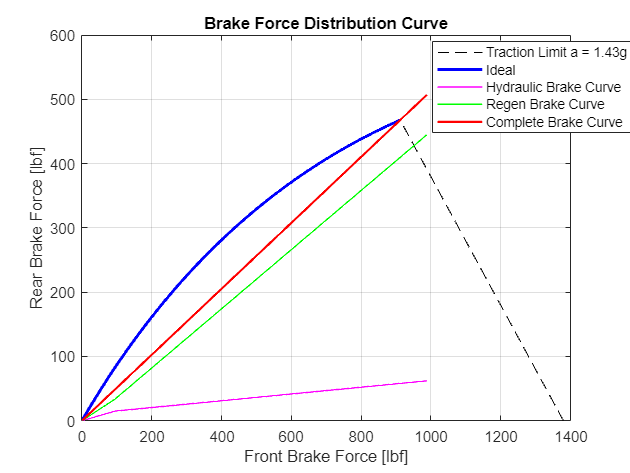

ideal_braking_Fb_r = F_f_list/beta;
regen_Fb_r = ideal_braking_Fb_r - F_r_list;
total_brake_curve = F_r_list + regen_Fb_r;

% Plotting regen curve
plot(F_f_list,regen_Fb_r,'g','LineWidth',1)
plot(F_f_list,total_brake_curve,'r','LineWidth',1.5)
legend('Traction Limit a = 1.43g','Ideal','Hydraulic Brake Curve','Regen Brake Curve','Complete Brake Curve');